# **IO512 - Loopback**

This example shows you how to perform a loopback test with the IO512 SDLC/HDLC I/O module, to verify the basic serial protocol communication over the **Transmit** and **Receive** channels.

The IO512 features four independent serial channels configured for SDLC and HDLC communication, with a high-speed **Integrated Universal Serial Controller** for the protocol-specific overhead. Each serial channel has independent, 32-Kbyte, transmit and receive FIFOs to reduce data loss at high clock rates.

The Simulink model features the [IO512 HDLC/SDLC - Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io512_setup_v4), [IO512 - Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io512_write_v4) and [IO512 - Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io512_read_v4) blocks.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO512 serial module installed       

- Connector cable from the I/O module to the terminal board

- Terminal board with eight jumper wires

### Test Setup

In this example, data is sent from Transmit channel 1 to Receive channel 3, and from Transmit channel 2 to Receive channel 4. You must therefore connect the pins on the terminal board where the Transmit and Receive channels are located. 

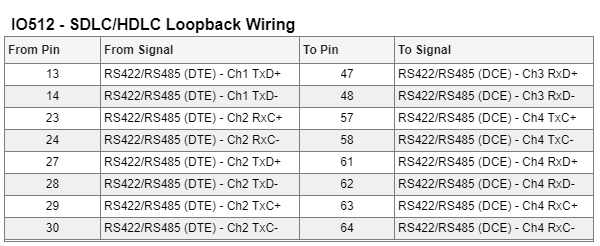

For the complete pin mapping of the I/O module please refer to the following documentation page: [IO512 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io512_pin_mapping)

## Open the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_IO512_Loopback';
open_system(modelName);

### Model Description

In the model, a sine wave signal is packed into a HDLC/SDLC frame with a header using a [Byte Packing](https://www.mathworks.com/help/slrealtime/io_ref/bytepacking.html) block and is transmitted by channel 1. Channel 2 transmits a 32-bit counter value, a header and additional padding bytes to achieve the same frame length.

On the receiving side, the data from the software buffer, the size of which is defined in the [IO512 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io512_setup_v4) block, can be extracted directly. To make sure that only a complete frame is transferred to the software buffer, the FIFO interrupt level is set to a value greater than the size of the frame, but still smaller than the software buffer in order to prevent overflows. The frame received is then spilt up in the header part and the packed signal. A [Selector](https://mathworks.com/help/simulink/slref/selector.html) and a [Byte Unpacking](https://www.mathworks.com/help/slrealtime/io_ref/byteunpacking.html) block are used to extract the original signals. The channel index from the header is used to verify that the data from the corresponding transmit channel is received.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check if the loopback is working as expected, open the first Simulink scope connected to the Receive channel 3 block and the second scope connected to the Receive channel 4 block. In the first scope, a sine wave signal, the number of bytes received and the message index must be displayed. On the second scope, a counter signal, the number of bytes received and the message index must be displayed:

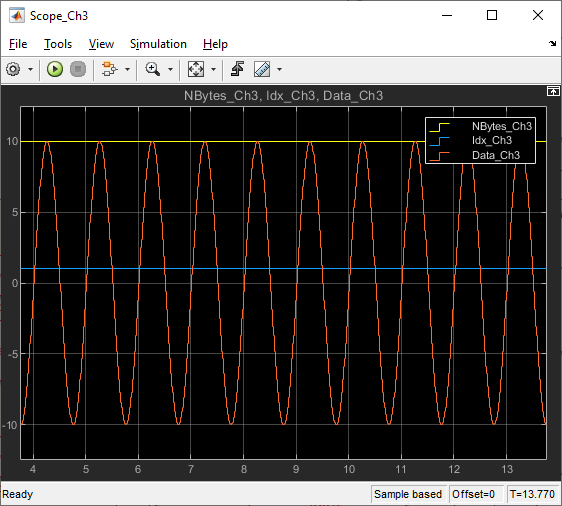 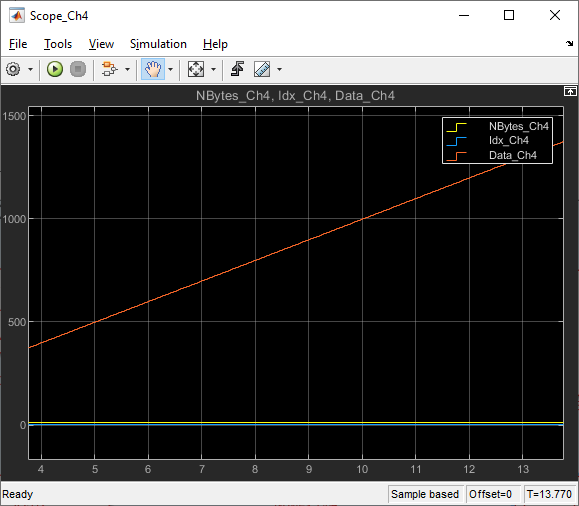

## Additional References

- [IO512 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io512)

- [Serial Usage Notes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_usage_notes)